Live scripts are like Markdown for R. Can combine code with visuals and text. We can chain commands on one line using commas to separate them.

x = 4, y = pi/x

x = 4

y = 0.7854

We see there are now interactive output. Can still break code into sections. Sections can be run independently or all sections can be run at once. Different display options are available to display the output inline or on the side. We can even choose to hide the code that generated the output.

Clicking on the output will show the code that generated that output. Clicking on the code will likewise show the output generated.

Run button will only run code for that section. Running code for one section will not change variables for other sections.

Ctrl + Enter will run code for a section

## Matricies

We can add formatting to text here as well. 

Scalars in MATLab are treated as 1x1 matricies.

x = 3

x = 3

We can create matricies in Matlab with square brackets.

y = [1 2]

y =      1     2


Values separated by spaces or commas are in the same row. Semicolons allow you to create a column

rowvec = [1 2 2 12]

rowvec =      1     2     2    12


rowvec2 = [1,2,3,4]

rowvec2 =      1     2     3     4


colvec = [1;2]

colvec =      1
     2


matrix1 = [1,2;2,1]

matrix1 =      1     2
     2     1


We can also perform calculations within the square brackets

calcvec = [2^2 abs(-pi)]

calcvec =     4.0000    3.1416


For sequential values, we can use the : command. Notice that brackets are not needed here.

rowvec = 1:6

rowvec =      1     2     3     4     5     6


The : operator defaults to a spacing between numbers of 1 but we can specify our own custom spacing. The middle number is the spacing.

rowvec = 1:0.5:3

rowvec =     1.0000    1.5000    2.0000    2.5000    3.0000


If instead we knew the first and last elements of the vector and we knew the total number of elements we want (inclusive) then we can use the linspace(first, last, # of elements) function

rowvec = linspace(0,1,4)

rowvec =          0    0.3333    0.6667    1.0000


Since both the : operator and the linspace operator create row vectors, we can create column vectors instead using the transpose operator '

colvec = rowvec'

colvec =          0
    0.3333
    0.6667
    1.0000


colvec2 = (1:4)'

colvec2 =      1
     2
     3
     4


notice that above we require the brackets to specify the order of operations. Otherwise it would take 4 transpose (which would just be 4)

rand(n) creates an nxn matrix of random numbers. We can also specify dimensions to create non-square matricies. Recall that a vector is simply a matrix with one column or row. randn(n) will create standard normal random numbers instead. (Recall we can express any normal random variable X = mu + sd*Z). The eye() function constructs the nxn identity matrix.

tworand = rand(2)

tworand =     0.4229    0.5985
    0.0942    0.4709


rand(2,3)

ans =     0.6959    0.6385    0.0688
    0.6999    0.0336    0.3196


randn(1,5)

ans =     0.1097    1.1287   -0.2900    1.2616    0.4754


eye(4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


zeros() and ones() will create a matrix of all 0 or 1 and functions same as the rand function

ones(2)

ans =      1     1
     1     1


ones(2,4)

ans =      1     1     1     1
     1     1     1     1


zeros(4)

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


zeros(4,1)

ans =      0
     0
     0
     0


size() function will return the dimensions of an existing matrix. Size function will return 2 dim vector of the rows and columns. We can specify whether we want rows or columns by specifying an additional parameter 1 or 2 to indicate just the row or column respectively. Use the length() function for vectors (with col or row size of 1)

x =ones(2,4)

x =      1     1     1     1
     1     1     1     1


size(x)

ans =      2     4


size(x,1)

ans = 2

size(x,2)

ans = 4

We can use the reshape(vec,row,col) function to turn a vector into a matrix. This will fill the values of the vector into the matrix column-wise

x = 1:20

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


y = reshape(x,4,5)

y =      1     5     9    13    17
     2     6    10    14    18
     3     7    11    15    19
     4     8    12    16    20


We can index a matrix and access its values

x = 0:2:10

x =      0     2     4     6     8    10


x(3) % access the third index of the vector

ans = 4

x(3:4) % get a two-dimensional vector of the third and fourth elements of x

ans =      4     6


x([2,4]) % can also be non-consecutive

ans =      2     6


x(4) = 73 % can assign values

x =      0     2     4    73     8    10



y = [1:5;6:10]

y =      1     2     3     4     5
     6     7     8     9    10


y(2,3)

ans = 8

y(2,:) % : refers to "all". So here we get all columns of second row

ans =      6     7     8     9    10


y(end,end) % end keyword is the last element of that dimension

ans = 10

If only one index is specified for a matrix, then it will traverse down each column from left to right until it reaches the specified index.

We can concatenate matricies with syntax similar to creating matricies. Dimensions must match in order to be able to concatenate.

A = [1 2 3]

A =      1     2     3


B = [4,5,6]

B =      4     5     6


C = [A;B] % vertical concatenation

C =      1     2     3
     4     5     6


D = [1 ;2]

D =      1
     2


E = [C D] % horizontal concatenation

E =      1     2     3     1
     4     5     6     2


Using the mean function on a matrix will generate a vector of column means. Specifying a parameter 2 will calculate the row means. Using the (:) command will change a matrix into a single vector(starting columnwise)

x = reshape(1:30,10,3)

x =      1    11    21
     2    12    22
     3    13    23
     4    14    24
     5    15    25
     6    16    26
     7    17    27
     8    18    28
     9    19    29
    10    20    30


mean(x)

ans =     5.5000   15.5000   25.5000


mean(x,2)

ans =     11
    12
    13
    14
    15
    16
    17
    18
    19
    20


mean(x(:))

ans = 15.5000

Other functions are the min and std functions

## Matrix Math

We can perform scalar addition and subtraction element-wise. Scalar division and multiplication are also done element-wise.

x = [1,2,3]

x =      1     2     3


y = [2,3,4]

y =      2     3     4


x = x + 2

x =      3     4     5


x = x - 2

x =      1     2     3


x = x/2

x =     0.5000    1.0000    1.5000


x = x*2

x =      1     2     3


We can add vectors of the same size to:

z = x + y

z =      3     5     7


Can find the maximum value of a vector with the max() function. This returns a scalar value

max(z)

ans = 7

There are also functions of matricies that perform the funtion element-wise

sqrt(z)

ans =     1.7321    2.2361    2.6458


round(sqrt(z),2)

ans =     1.7300    2.2400    2.6500


Matrix multiplication is done using the * symbol. This only works for matricies with dimensions that agree. If dimensions do not agree, will return an error.  The .* function allows us to do element-wise matrix multiplication.

A = rand(1,2)

A =     0.9686    0.5313


B = rand(2,1)

B =     0.3251
    0.1056


C = [1,1]

C =      1     1


A*B

ans = 0.3711

B*A % error as dimensions do not agree

ans =     0.3150    0.1728
    0.1023    0.0561


A.*C

ans = 1×2
    0.9686    0.5313


Some other behaviour occurs when we have matricies of not necessarity equal but still compatible size ( in MATLAB). Notice that spaces do not impact the declaration of matricies

x = [1 2;
    3 4;
    5 6;
    7 8].*[1;2;3;4]

x = 4×2
     1     2
     6     8
    15    18
    28    32


We can create and initialize multiple variables simultaneously using vector assignment

[xrow,xcol] = size(x)

xrow = 4

xcol = 2

xrow + xcol

ans = 6

The max function also outputs a vector of length two. The first element is the maximum value and the second is the index

[mval,mind] = max(B)

mval = 0.3251

mind = 1

If a function returns two outputs, we can extract only one of the outputs by using ~. 

[mvalA,~] = max(A)

mvalA = 0.9686

We can invert a matrix using the inv or pinv functions for the inverse and pseudoinverse respectively

x = rand(4)

x = 4×4
    0.6110    0.2665    0.5271    0.9436
    0.7788    0.1537    0.4574    0.6377
    0.4235    0.2810    0.8754    0.9577
    0.0908    0.4401    0.5181    0.2407


xinv = pinv(x)

xinv = 4×4
   -0.6889    2.2873   -0.8915    0.1877
    2.7665   -0.9941   -2.7412    2.6946
   -3.4656    1.3521    2.5081    0.0248
    2.6605   -1.9555   -0.0498   -0.8964


round(x*xinv,2)

ans = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


xinv = inv(x)

xinv = 4×4
   -0.6889    2.2873   -0.8915    0.1877
    2.7665   -0.9941   -2.7412    2.6946
   -3.4656    1.3521    2.5081    0.0248
    2.6605   -1.9555   -0.0498   -0.8964


round(x*xinv,2)

ans = 4×4
     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


We can use help function to look up functionality of a unknown function. doc function will open up the documentation for a function in its own window.

help max

 max    Maximum elements of an array.
    M = max(X) is the largest element in the vector X. If X is a matrix, M 
    is a row vector containing the maximum element from each column. For 
    N-D arrays, max(X) operates along the first non-singleton dimension.
 
    When X is complex, the maximum is computed using the magnitude
    max(ABS(X)). In the case of equal magnitude elements the phase angle 
    max(ANGLE(X)) is used.
 
    [M,I] = max(X) also returns the indices into operating dimension 
    corresponding to the maximum values. If X contains more than one 
    element with the maximum value, then the index of the first one 
    is returned.
 
    C = max(X,Y) returns an array with the largest elements taken from X or 
    Y. X and Y must have compatible sizes. In the simplest cases, they can 
    be the same size or one can be a scalar. Two inputs have compat

%doc max

## Plots

Create plots (lines only) with the plot function. plot(x,y). The optional plot arguement will plot red dashed lines with a circle market.

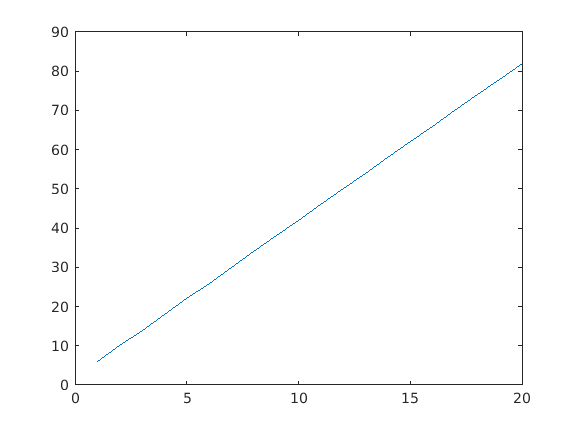

plot(1:20,2+4*(1:20))

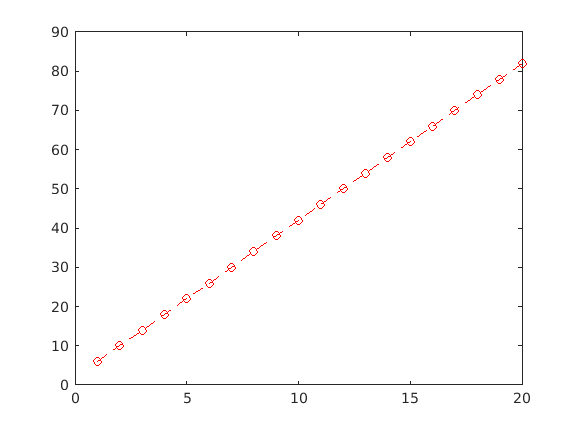

plot(1:20,2+4*(1:20), "r--o")

We can use the "hold on" function to add a line to an existing plot. The hold on command is a toggle. Any plots functions called afterward will continue adding to the same plot. We need to call hold off to turn off the hold state so that each plot is separate.

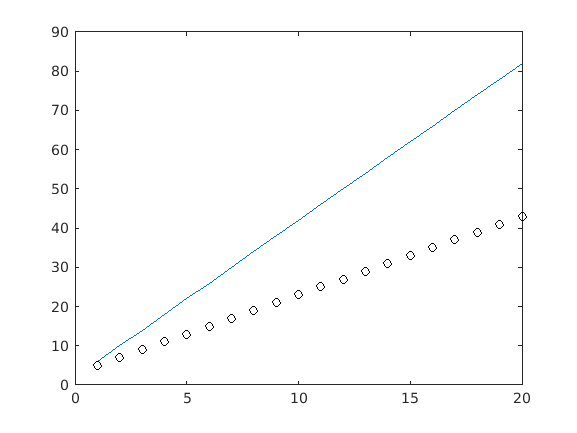

plot(1:20,2+4*(1:20))
hold on
plot(1:20,3+2*(1:20),"blacko")
hold off

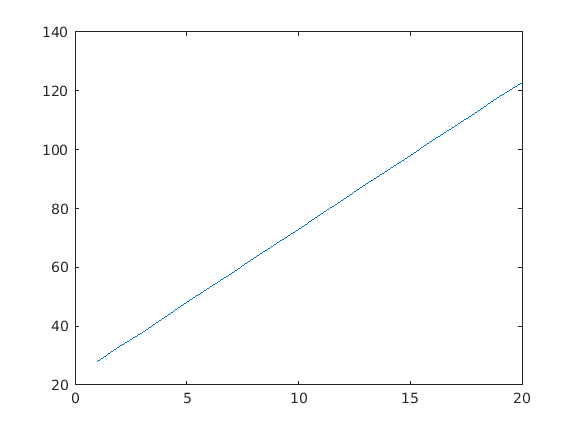

plot(1:20,23+5*(1:20))

If we plot a vector by itself, MATLAB will treat it as the y values in the plot and automatically put 1 to n as the x values.

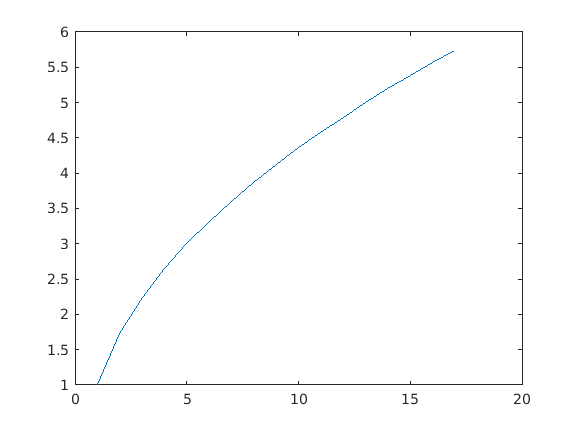

plot(sqrt(1:2:33))

Can also specify pairs of additional inputs with a property name and its associated value

plot(1:10,"ro-","LineWidth",3)

Other plot functions have their own customization features.

Can add title, labels, legend, change axis limits to an existing plot with the title function.

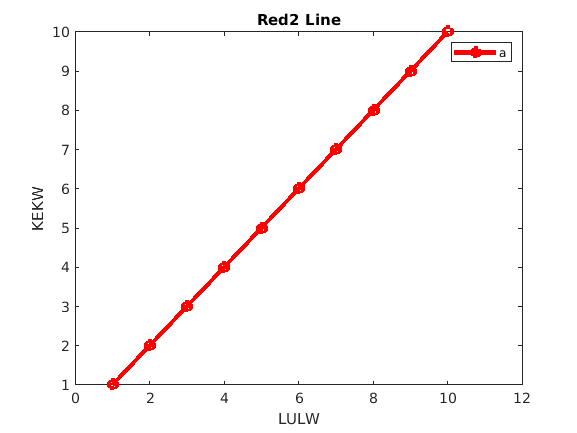

title("Red Line")
ylabel("KEKW")
xlabel("LULW")
legend("a") % one label for each line. 
title("Red" + 2 + " Line") % can also concatenate numbers and strings
xlim([0 12])

## Importing into MATLAB

.mat files will import all variables in the file

.jpg file will import as a numeric array of pixel values

.csv files and other text files will open up the import window to previw the data to be imported. Any missing values will be NaN (not a number). A table is the default import structure for data.

To get data from a table, use the dot notation "data.VarName"

We can assign new values to a table column in the same way as a matrix

table = sortrows(table, "varName") is used to sort a table by values in the given column.

we can also use the regular dot notation to extract rows and values from a table (:,end)

## Logical Operators

We use relational operators such as <, >, ==, ~=, <=, >=  are used to compare two values. Outcome of these comparisons is either 1 or 0 (true or false)

Logical comparisons of a scalar to a matrix of vector will do the comparisons element-wise and return a matrix of the same size.

1:5 > 3

ans = 1×5 logical array
   0   0   0   1   1


We can use logical vectors to get values from a vector

x = 1:10

x = 1×10
     1     2     3     4     5     6     7     8     9    10


y = x(x>4)

y = 1×6
     5     6     7     8     9    10


We can use the and (&) and or (|) to combine logical comparisons

## Simple Control Structures

### If Statement

x = -9

x = -9

if x > -1
    y = sqrt(x)
end

if x > -1
    y = sqrt(x)
else 
    y = sqrt(abs(x))
    disp("negative number")
end

y = 3

negative number


elseif statement can also be used for more conditions

### For Statement

break and continue statements can also be used in a for loop

y = 0

y = 0

for i = 1:10
    y = y + i;
    pause(0.1) % pause the loop for 0.1 seconds
end
y

y = 55

Visually allow changing values by user.

s = 1

s = 1

### While Loop

Will iterate until the statement evaluates to false

x = 0

x = 0

while x < 10
    x = x+2
end

x = 2

x = 4

x = 6

x = 8

x = 10

## Functions

Functions must be declared at the end of a .m script file

addTwoNums(2,3)

sum = 5

ans = 5

We can pass a function to another function by turning it into a function handle using the @ syntax

makeSum(@addTwoNums,4,6)

sum = 10

s = 10

ans = 10

function sum = addTwoNums(num1,num2)
    sum = num1 + num2
end

function s = makeSum(f,x1,x2)
    s = f(x1,x2)
end
